# DC Motor Analysis

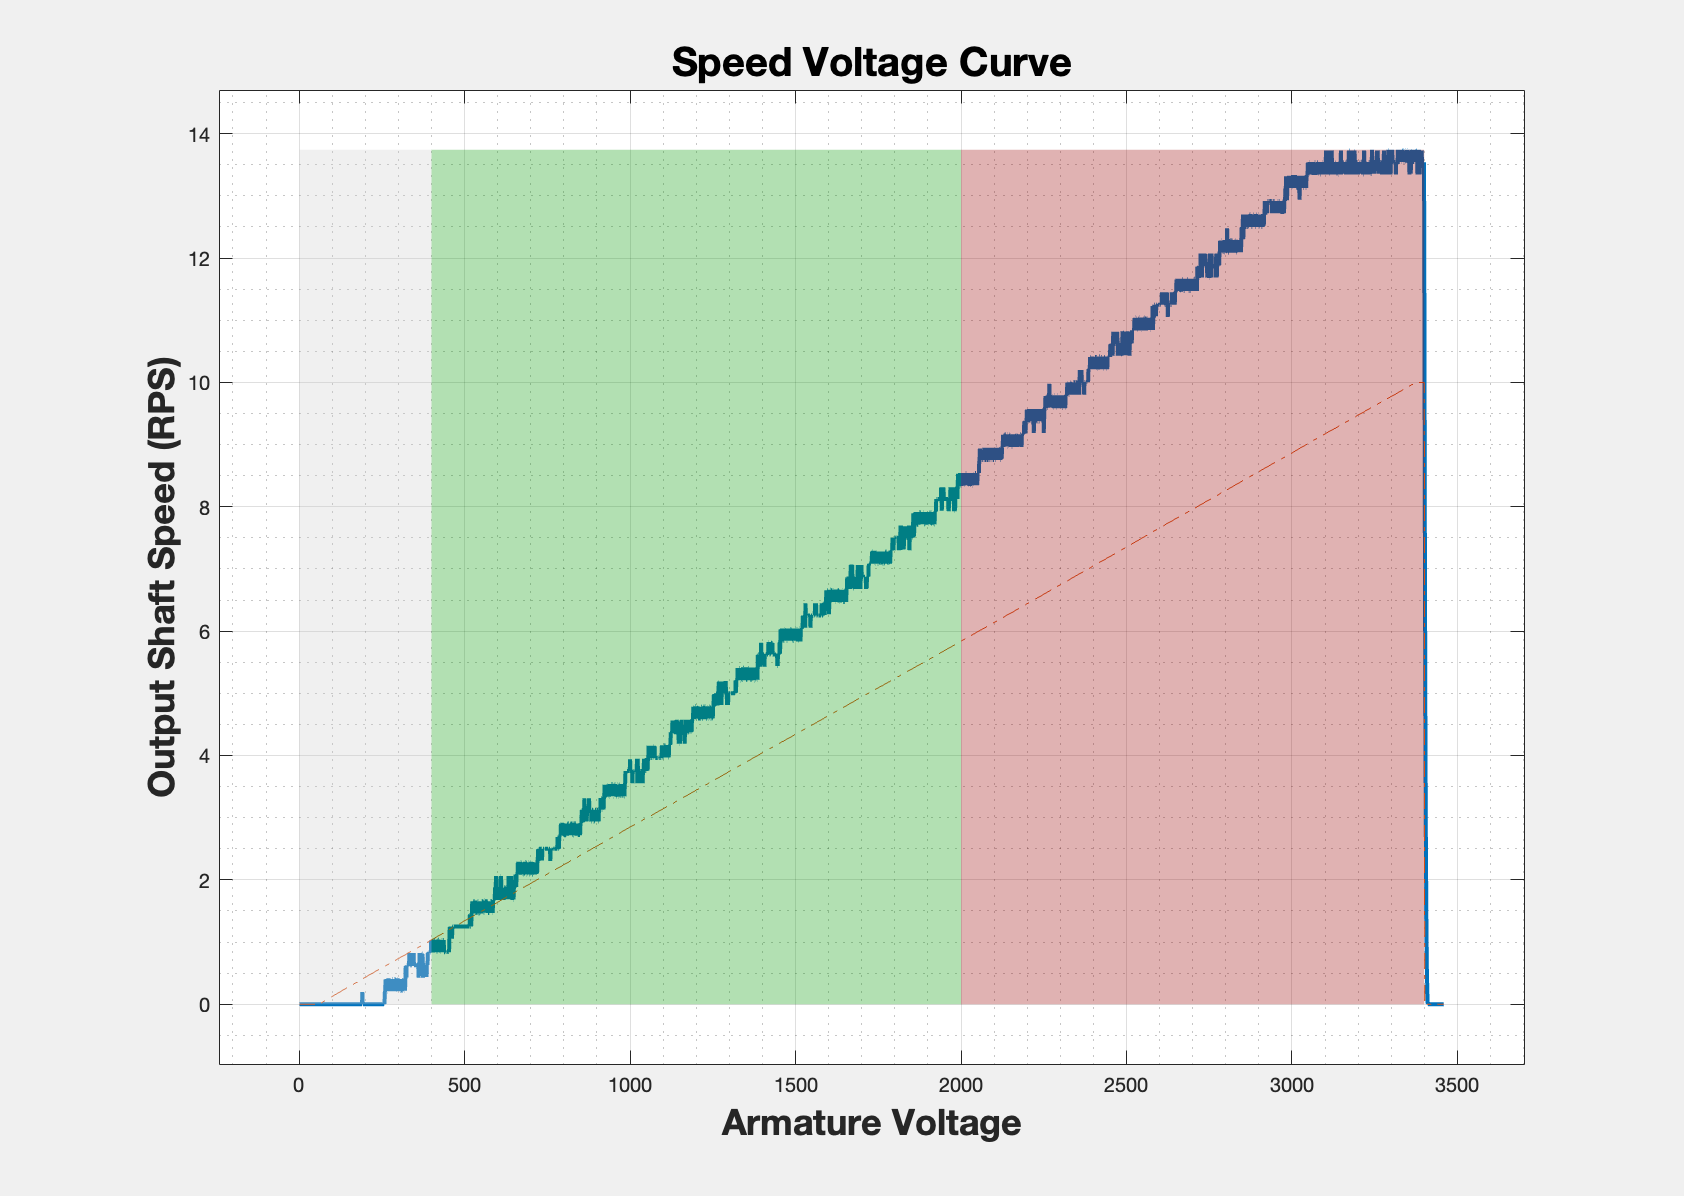

% Open and Closed loop Input Output Data Processesing
% Saves plots as PDFs
clear; clc; close all;
addpath("utils/")
folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
%%%%%%%%%%%%%%%%% Preprocess OpenLoop Datasets
[~, ramp_rps, ramp_volt, ~] = extractMotorData("DataSets/MotorIdentification/ramp10_100.csv");
[~, sin1_1_rps, sin1_1_volt, ~] = extractMotorData("DataSets/MotorIdentification/sin_1_1_100.csv");
[~, sin5_5_rps, sin5_volt, ~] = extractMotorData("DataSets/MotorIdentification/sin_5_5_100.csv");
[~, sin1_8_rps, sin1_8_volt, ~] = extractMotorData("DataSets/MotorIdentification/sin_1_8_100.csv");
[~, step_rps, step_volt, ~] = extractMotorData("DataSets/MotorIdentification/openStep.csv");
[~, trig_rps, trig_volt, ~] = extractMotorData("DataSets/MotorIdentification/openTrig.csv");
%%%%%%%%%%%% Speed-Voltage Curve 
fig = figure;
plot(ramp_rps, 'LineWidth', 2);  hold on;
plot(ramp_volt, 'LineStyle','-.');
t = linspace(0,0.02 ,length(ramp_volt));
c = polyfit(t,ramp_rps, 1);
y_min = min(ramp_rps);
y_max = max(ramp_rps);
y_height = y_max - y_min;
% Nominal Operation Section
x_start = 400; 
x_width = 1600;
rectangle('Position', [x_start, y_min, x_width, y_height], ...
          'FaceColor', [0.0 0.6 0 0.1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
% Overdrive Section
x_start = 2000; 
x_width = 1400;
rectangle('Position', [x_start, y_min, x_width, y_height], ...
          'FaceColor', [0.6 0.0 0 0.1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
% DeadZone Section
x_start = 0; x_width = 400;
rectangle('Position', [x_start, y_min, x_width, y_height], ...
          'FaceColor', [0.8 0.8 0.8 0.1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
hold off;
grid on; grid minor; 
axis padded;
title("Speed Voltage Curve", 'FontSize', 20, 'FontWeight', 'bold'); 
ylabel("Output Shaft Speed (RPS)", 'FontSize', 18, 'FontWeight', 'bold'); 
xlabel("Armature Voltage", 'FontSize', 18, 'FontWeight', 'bold');
set(fig, 'Units', 'inches', 'Position', [0 0 11.7 8.3]);
set(gcf,'Visible', 'on');
exportgraphics(fig, fullfile(folderpath, "Speed_Voltage_Curve.pdf"));

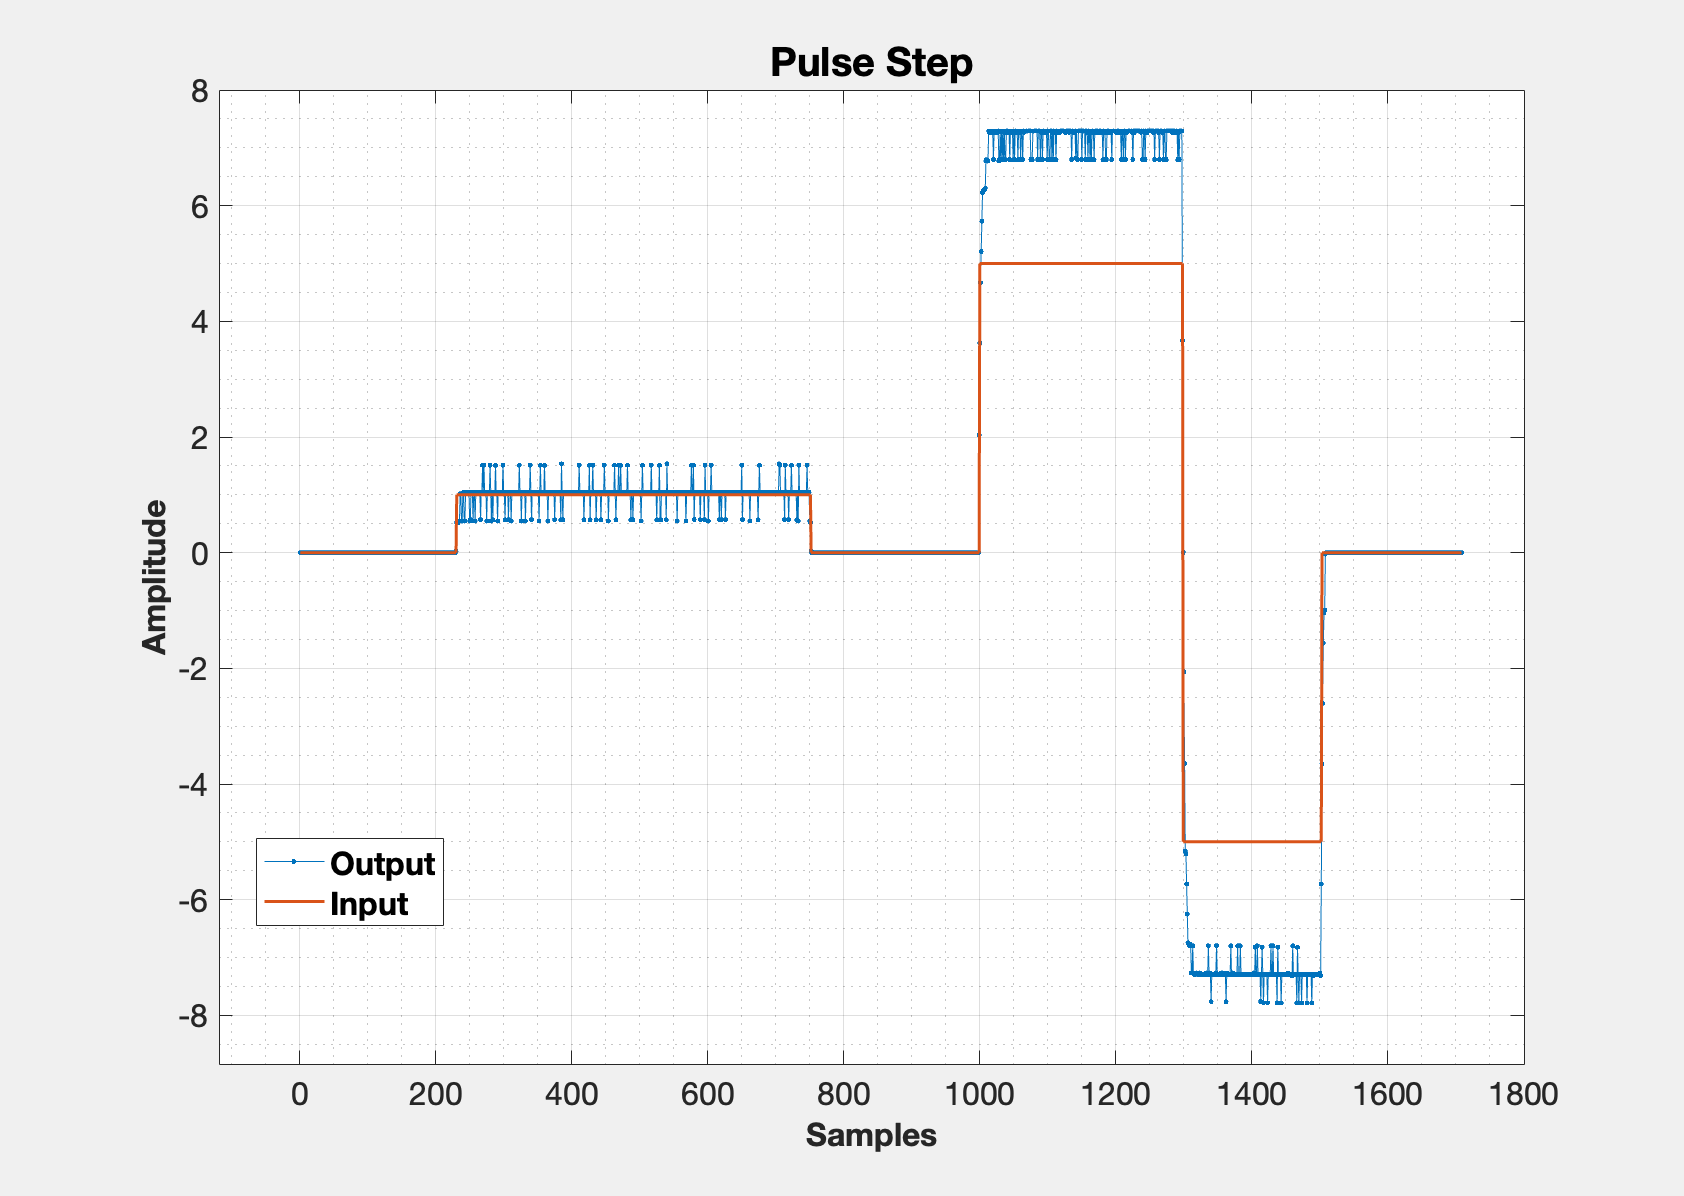

%%%%%%%%%%%%%%%%%%%%%% Plot Open Loop Data 
graphInOutData(step_rps(200:end), step_volt(200:end),'Pulse_Step', folderpath);

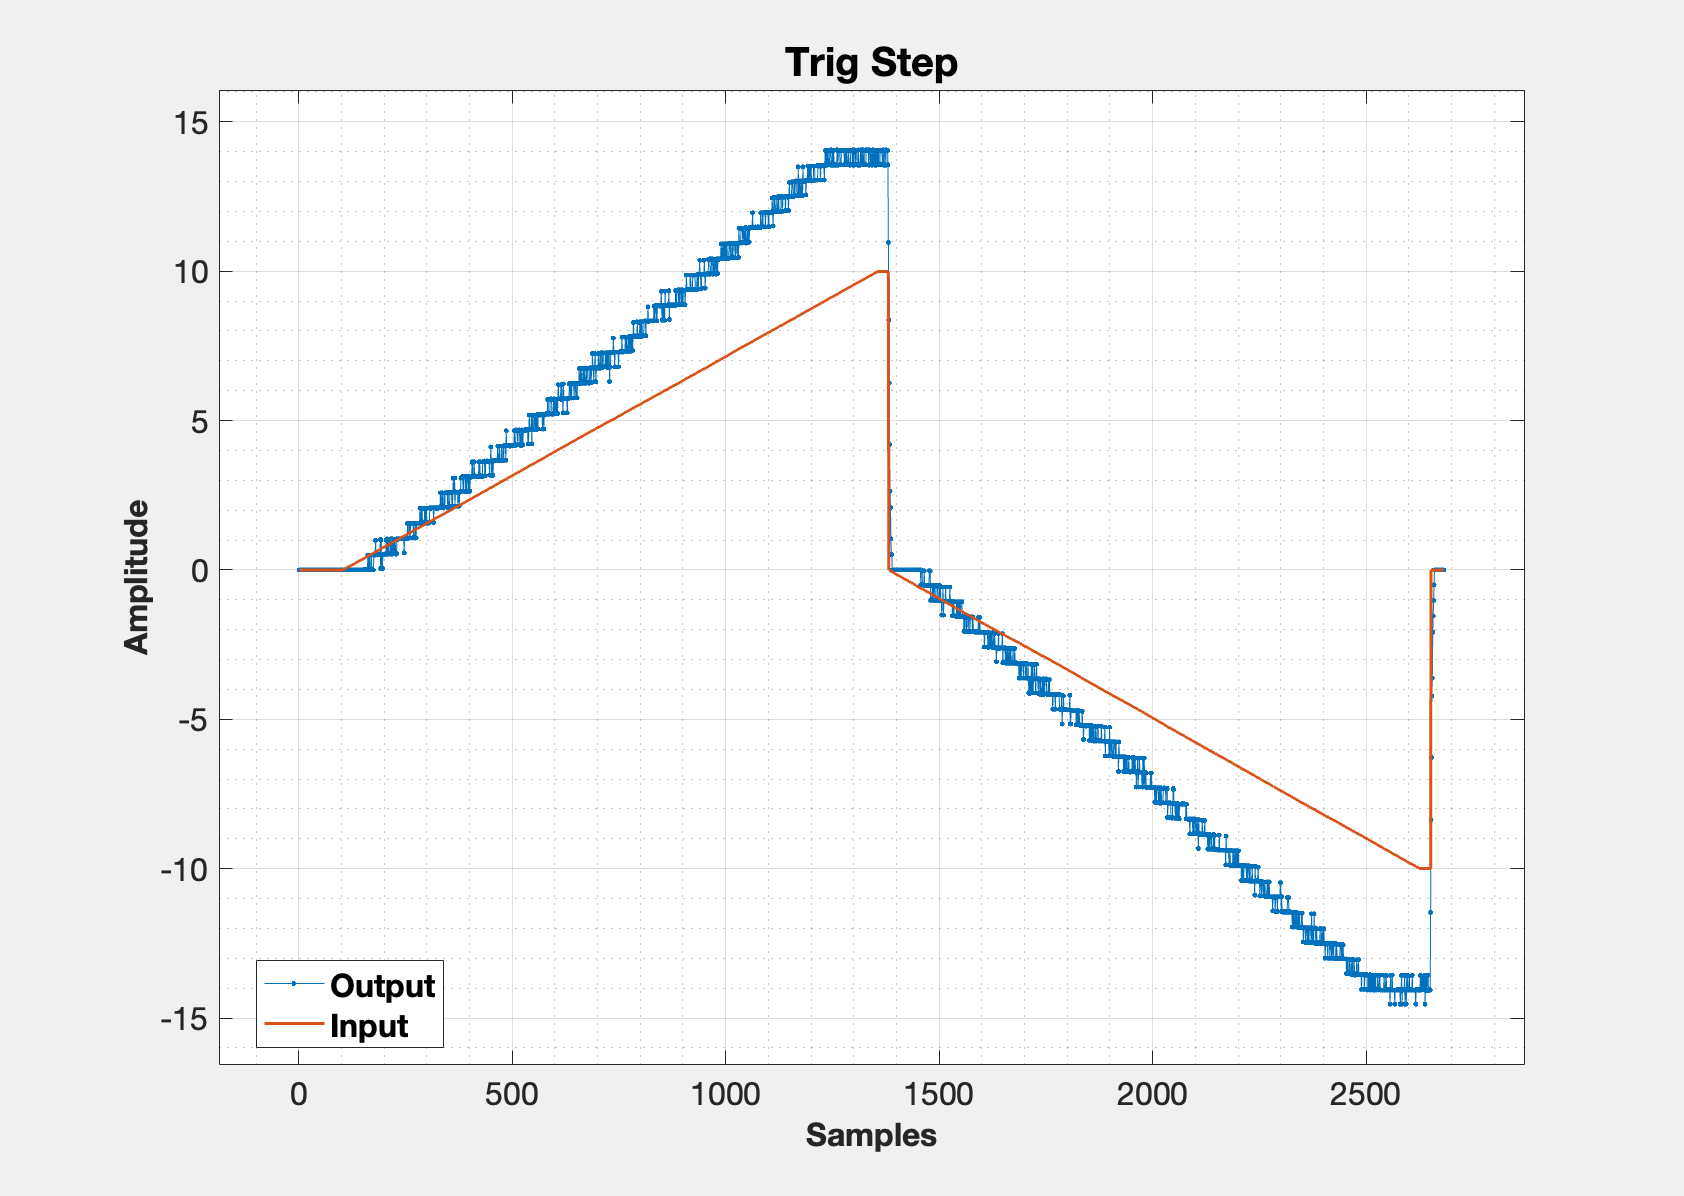

graphInOutData(trig_rps, trig_volt, 'Trig_Step', folderpath);

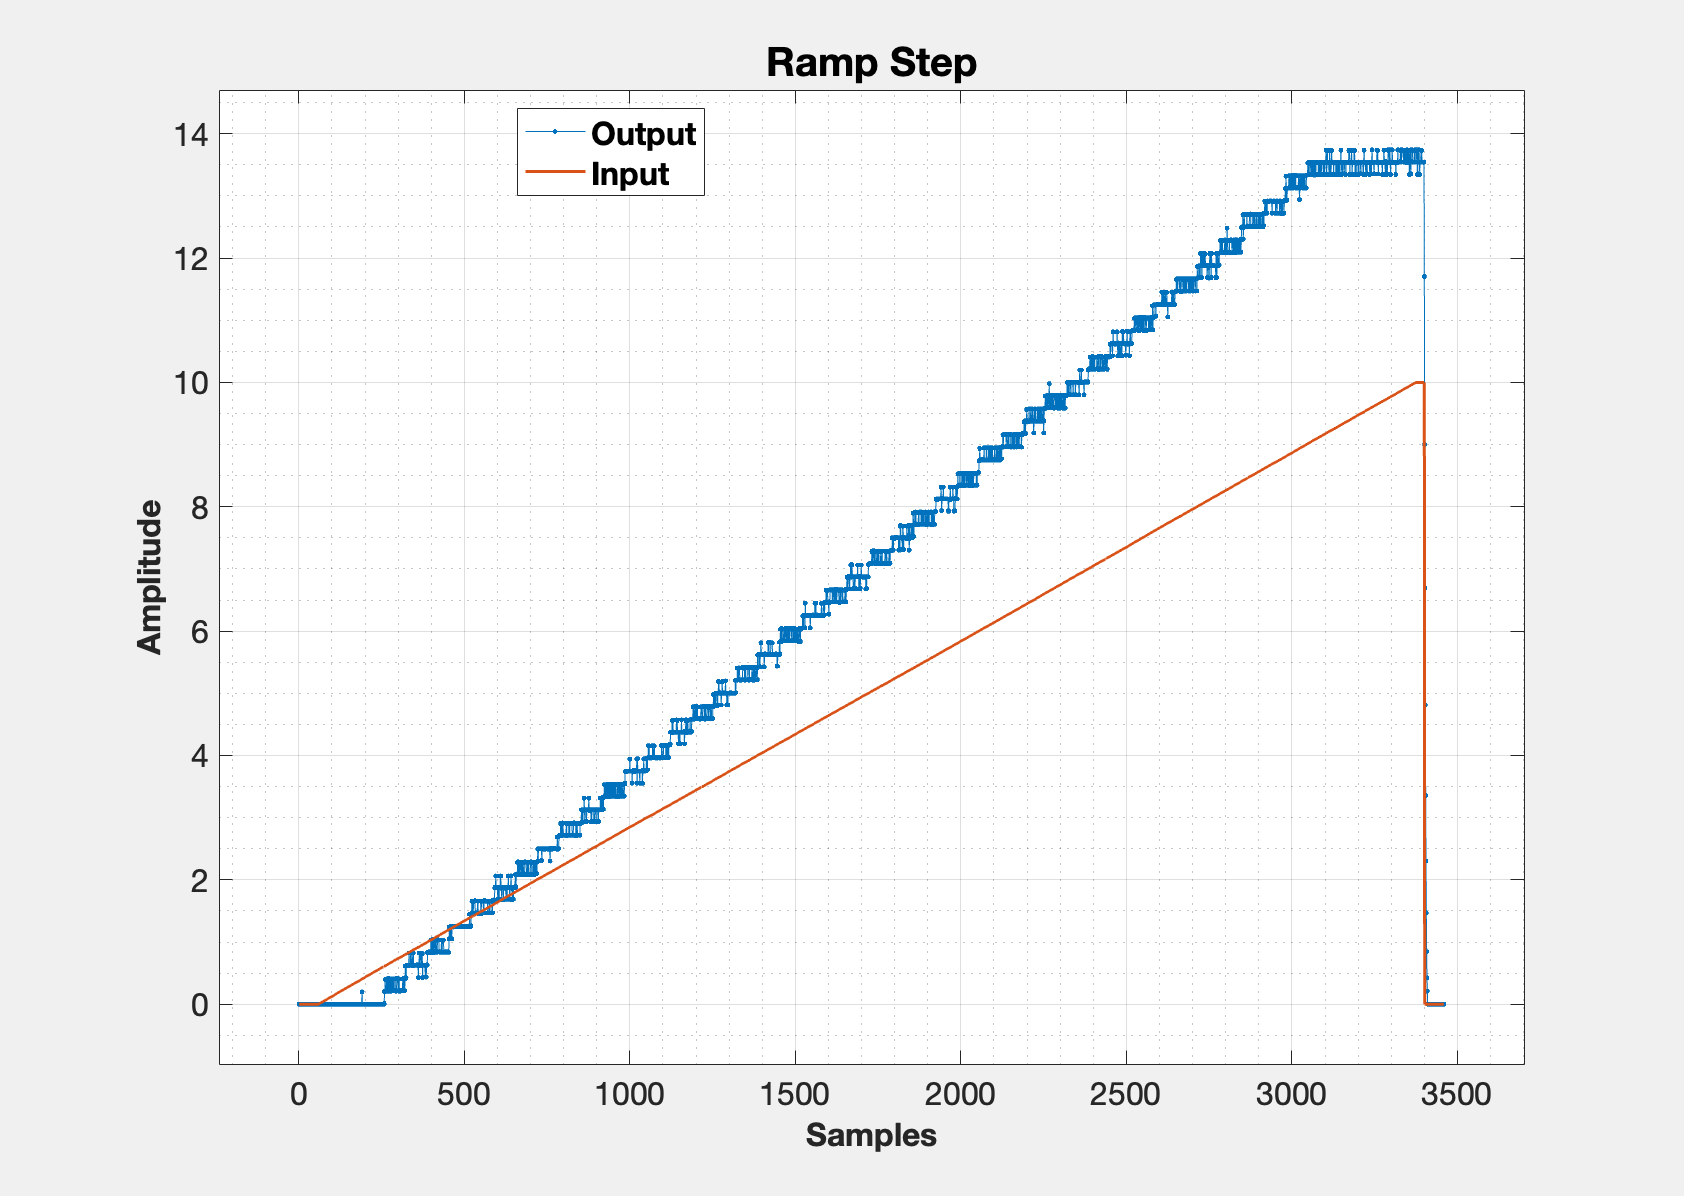

graphInOutData(ramp_rps, ramp_volt, 'Ramp_Step', folderpath);

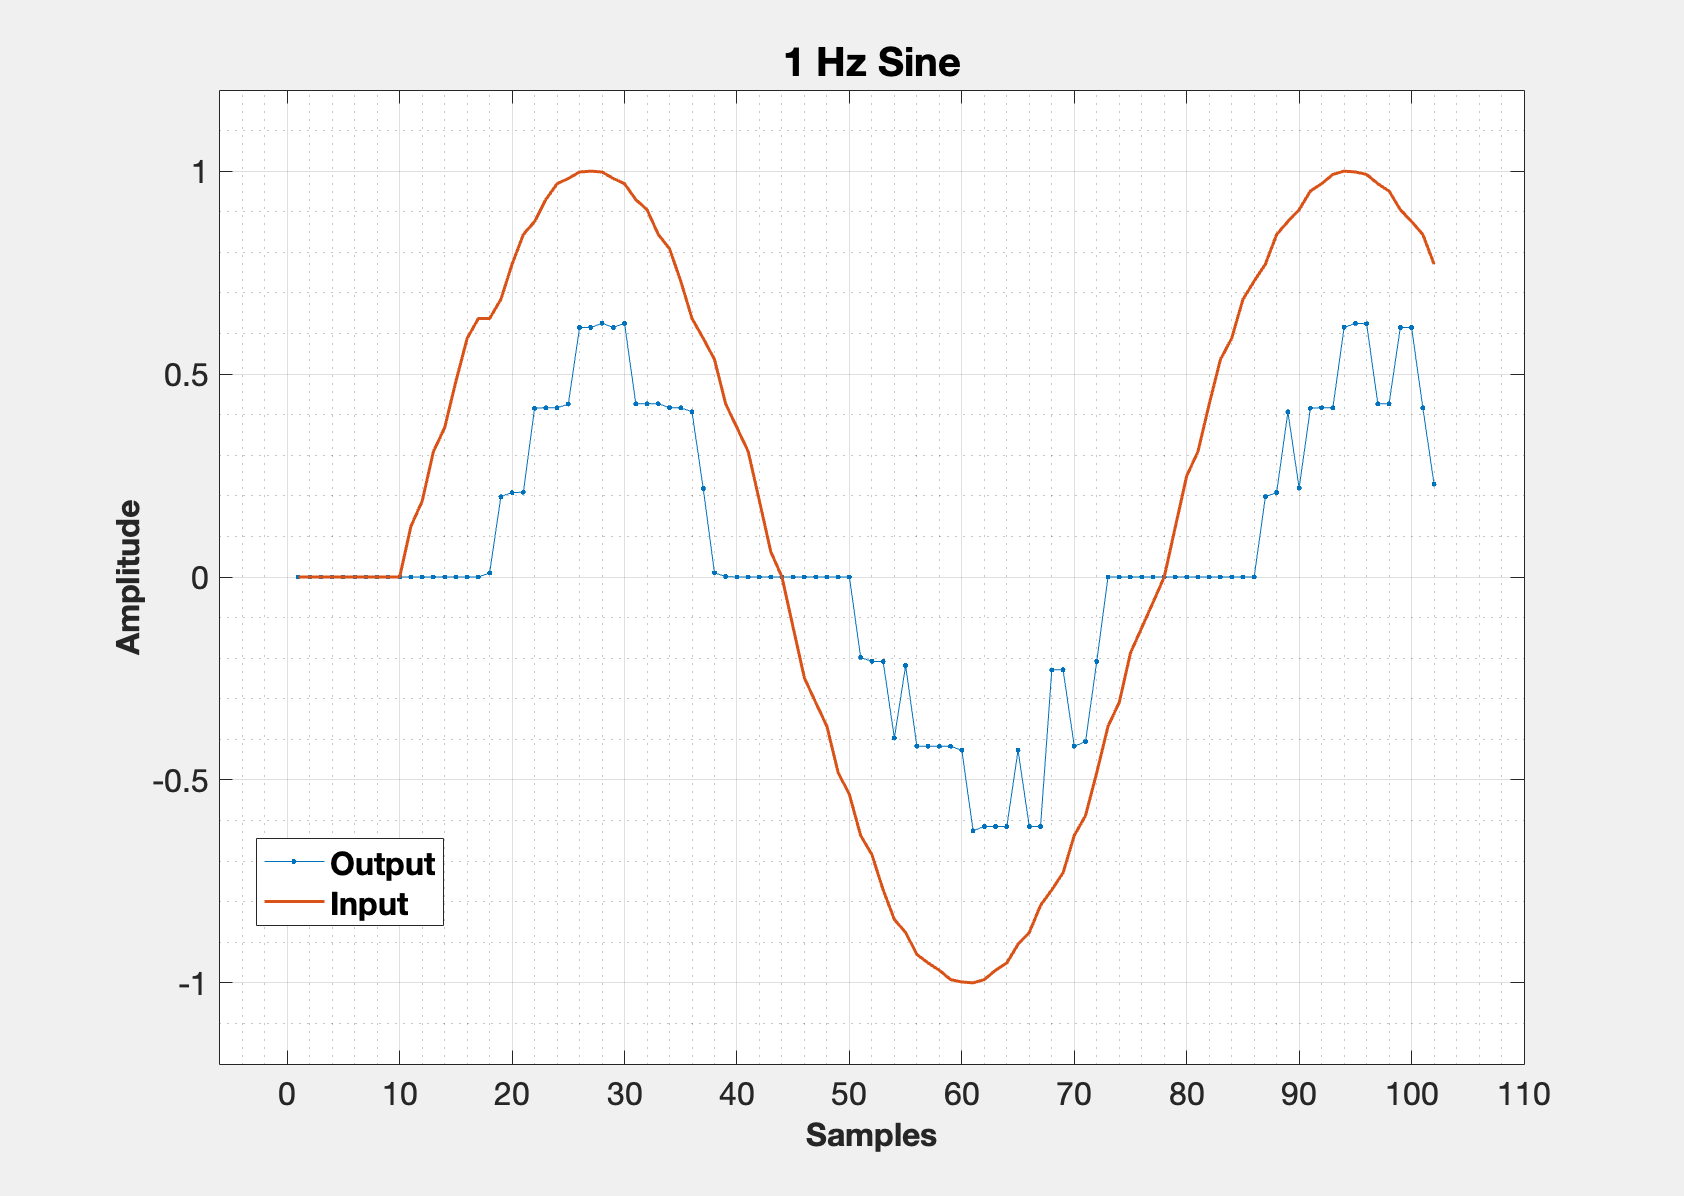

graphInOutData(sin1_1_rps(100:201), sin1_1_volt(100:201), '1_Hz_Sine', folderpath);

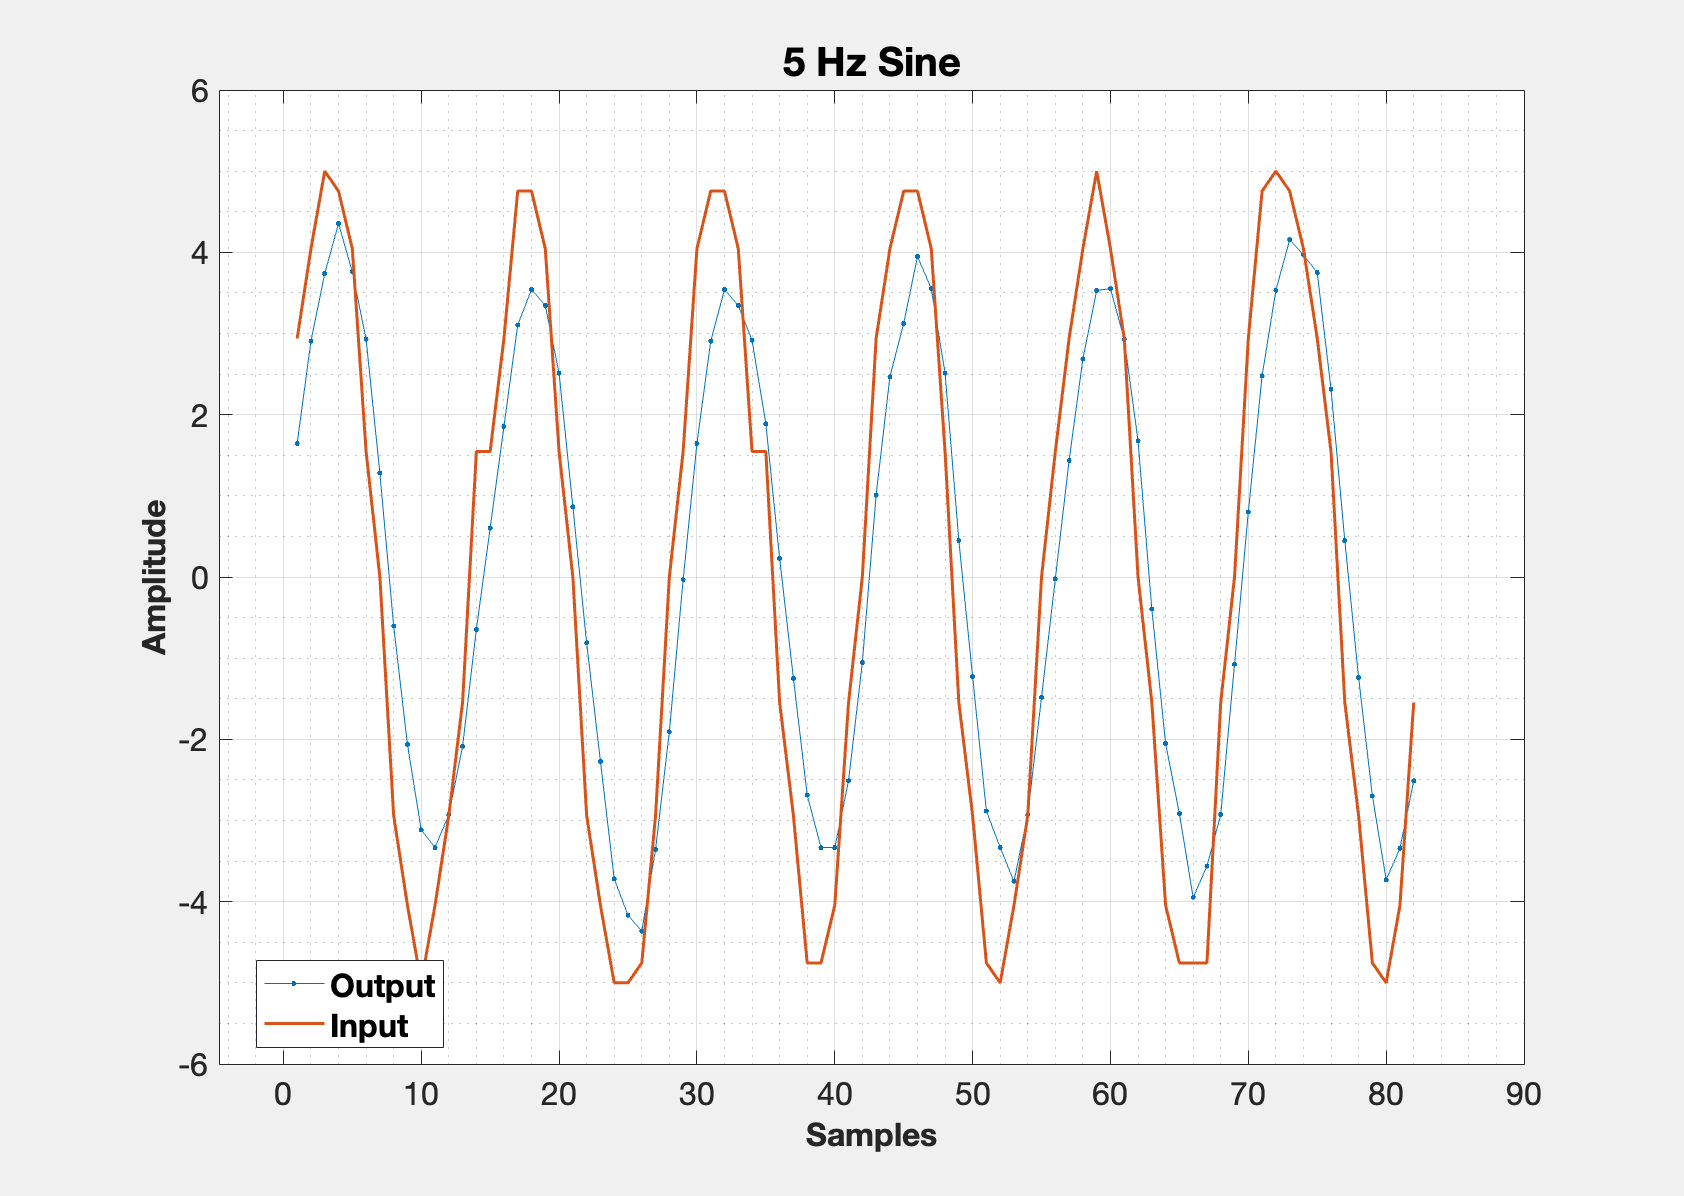

graphInOutData(sin5_5_rps(65:146), sin5_volt(65:146), '5_Hz_Sine', folderpath);

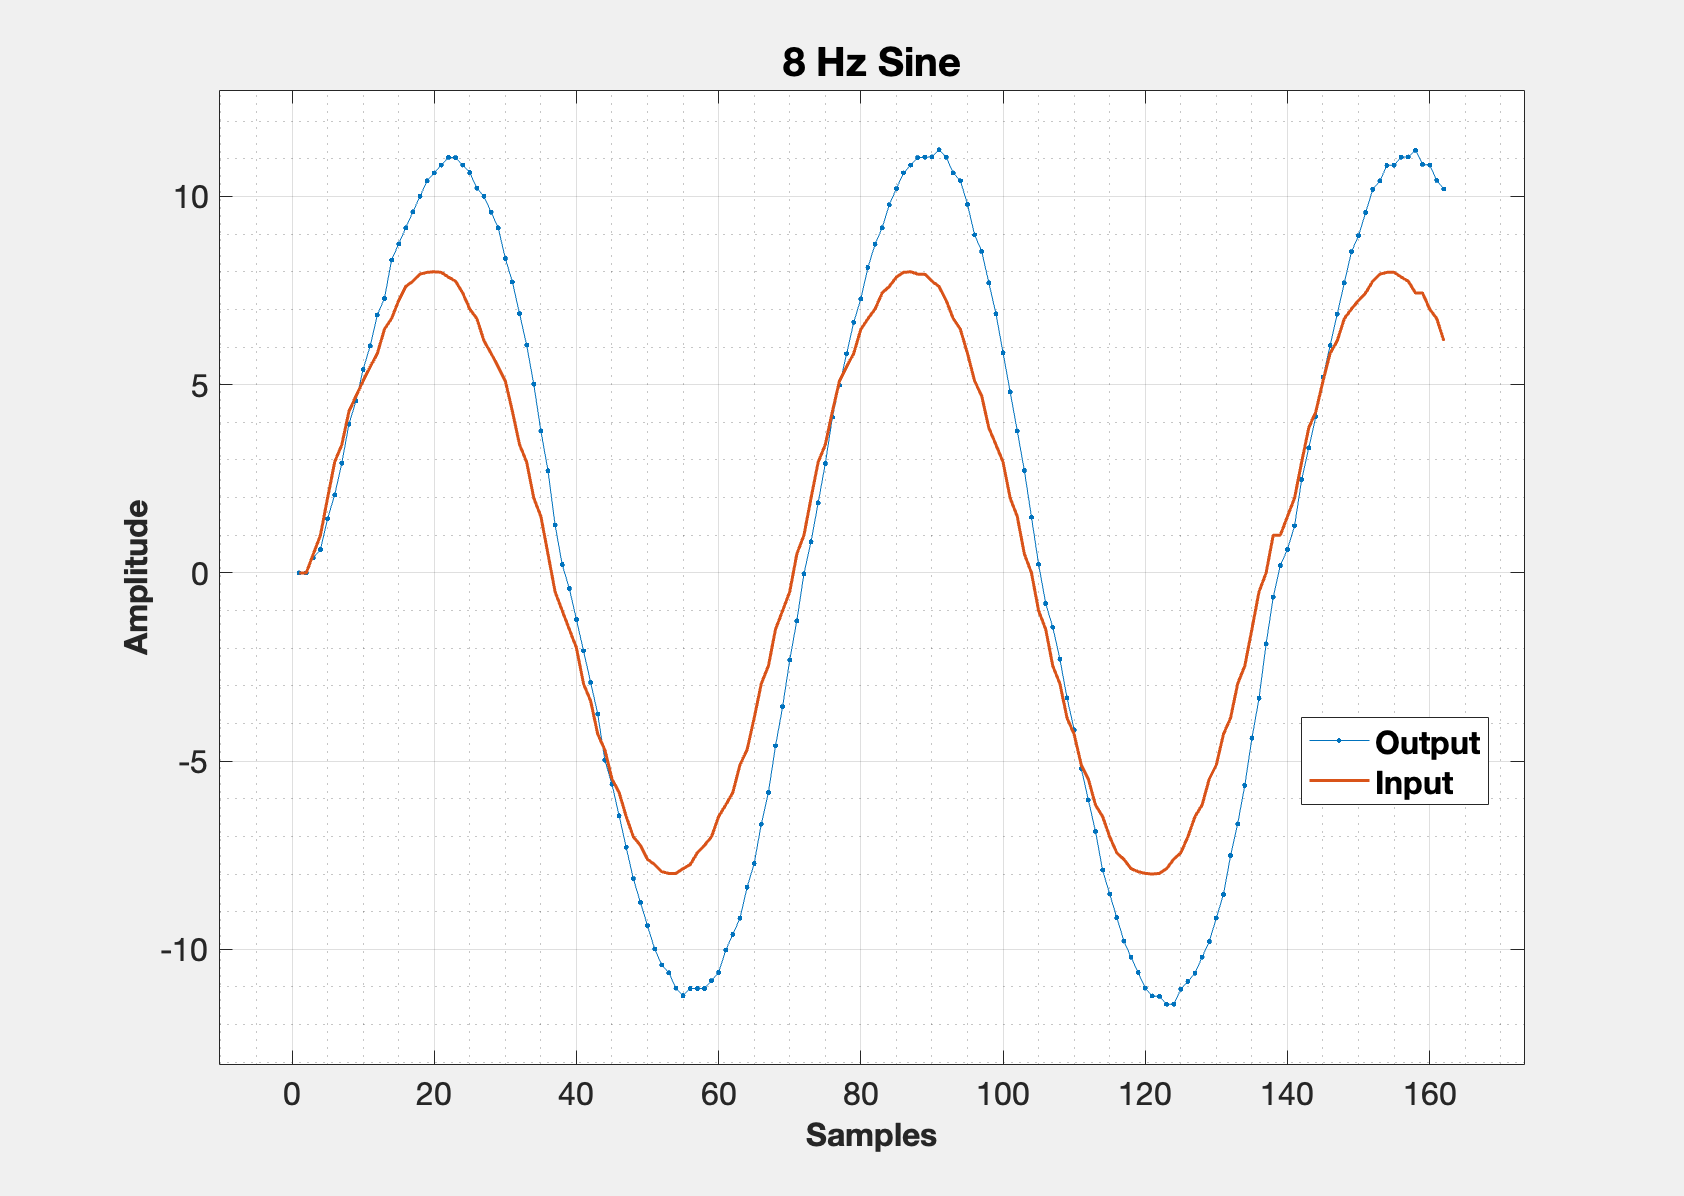

graphInOutData(sin1_8_rps(40:201), sin1_8_volt(40:201), '8_Hz_Sine', folderpath);

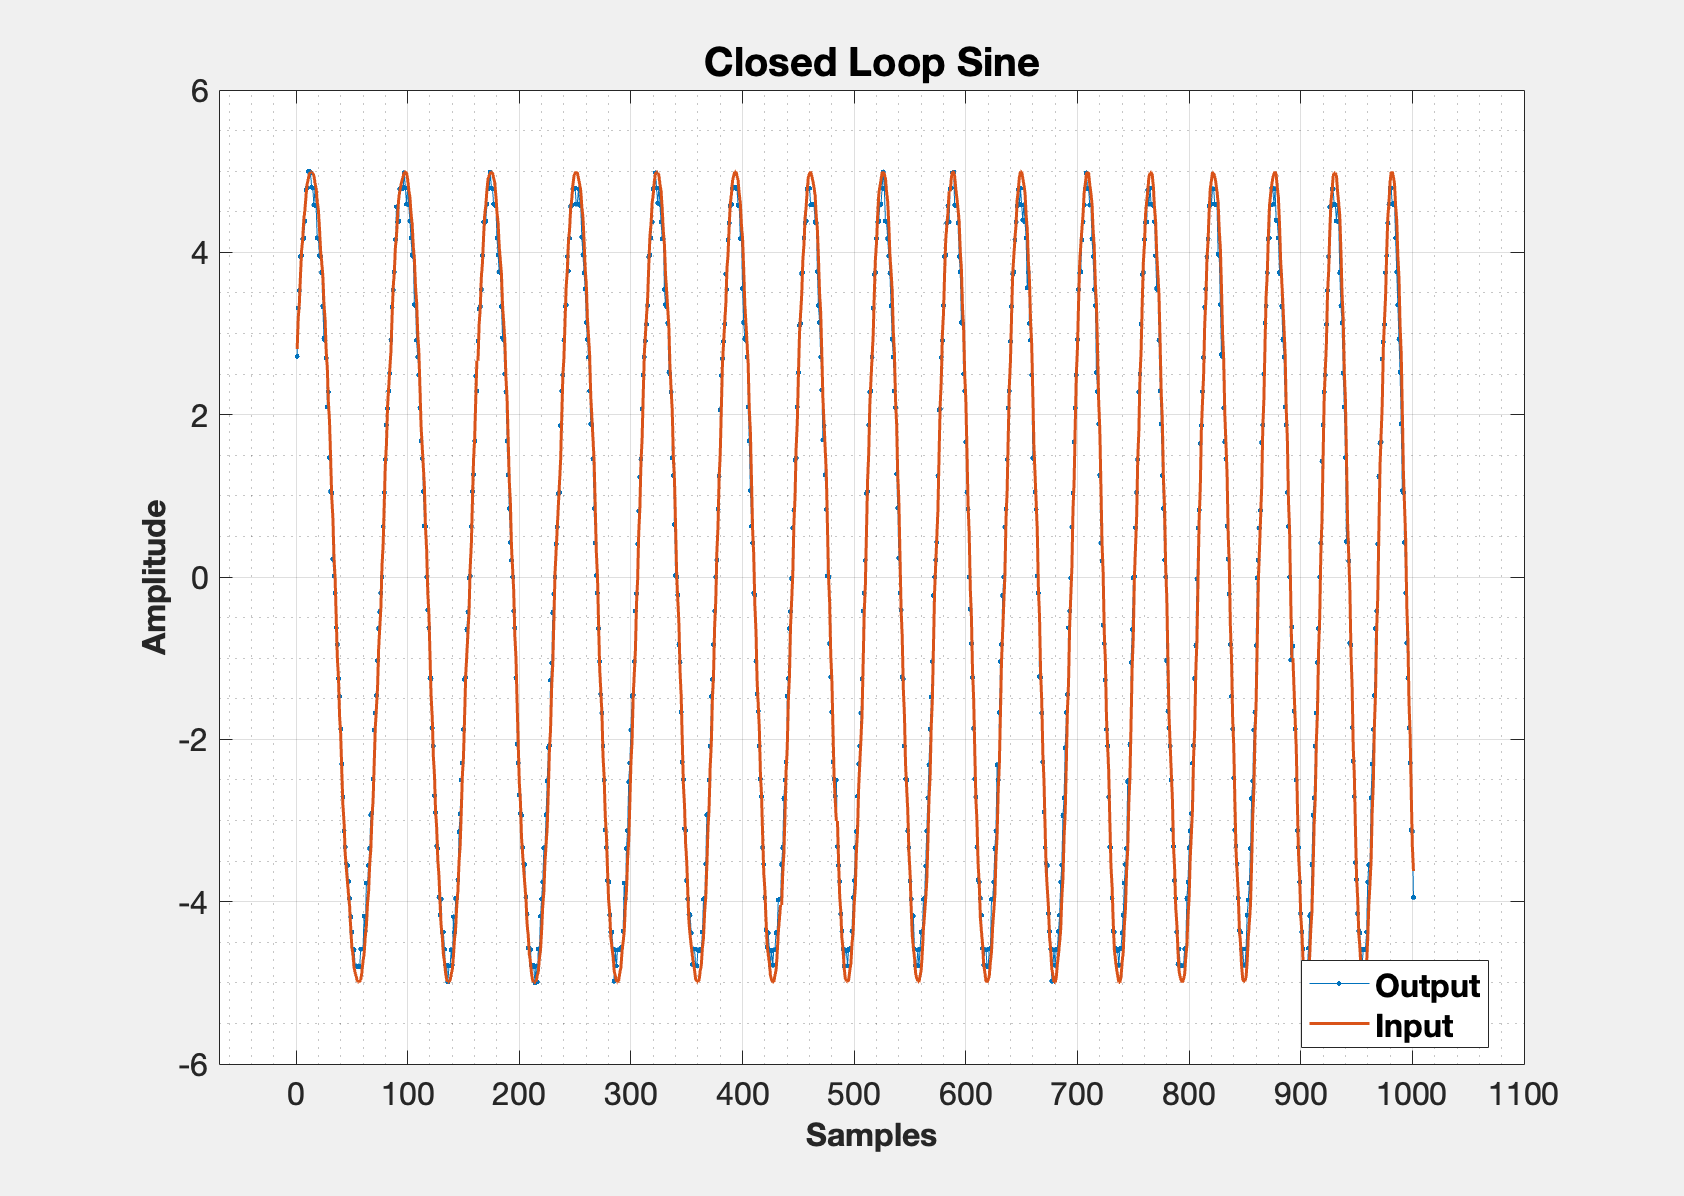

%%%%%%%%%%%%%%% Preprocess Closed Loop DataSets
[timestamps, cl_step_rps, cl_step_ref, cl_step_u ] = extractMotorData("DataSets/MotorIdentification/cl_zn_step.csv");
[~, cl_chirp_rps, cl_chirp_ref, cl_chirp_u] = extractMotorData("DataSets/MotorIdentification/cl_zn_chrip8_1.csv");
%%%%%%%%%%%%%%%%%%%%% Plot Closed Loop Data 
graphInOutData(cl_chirp_rps(1301:2301), cl_chirp_ref(1301:2301), 'Closed_Loop_Sine', folderpath);

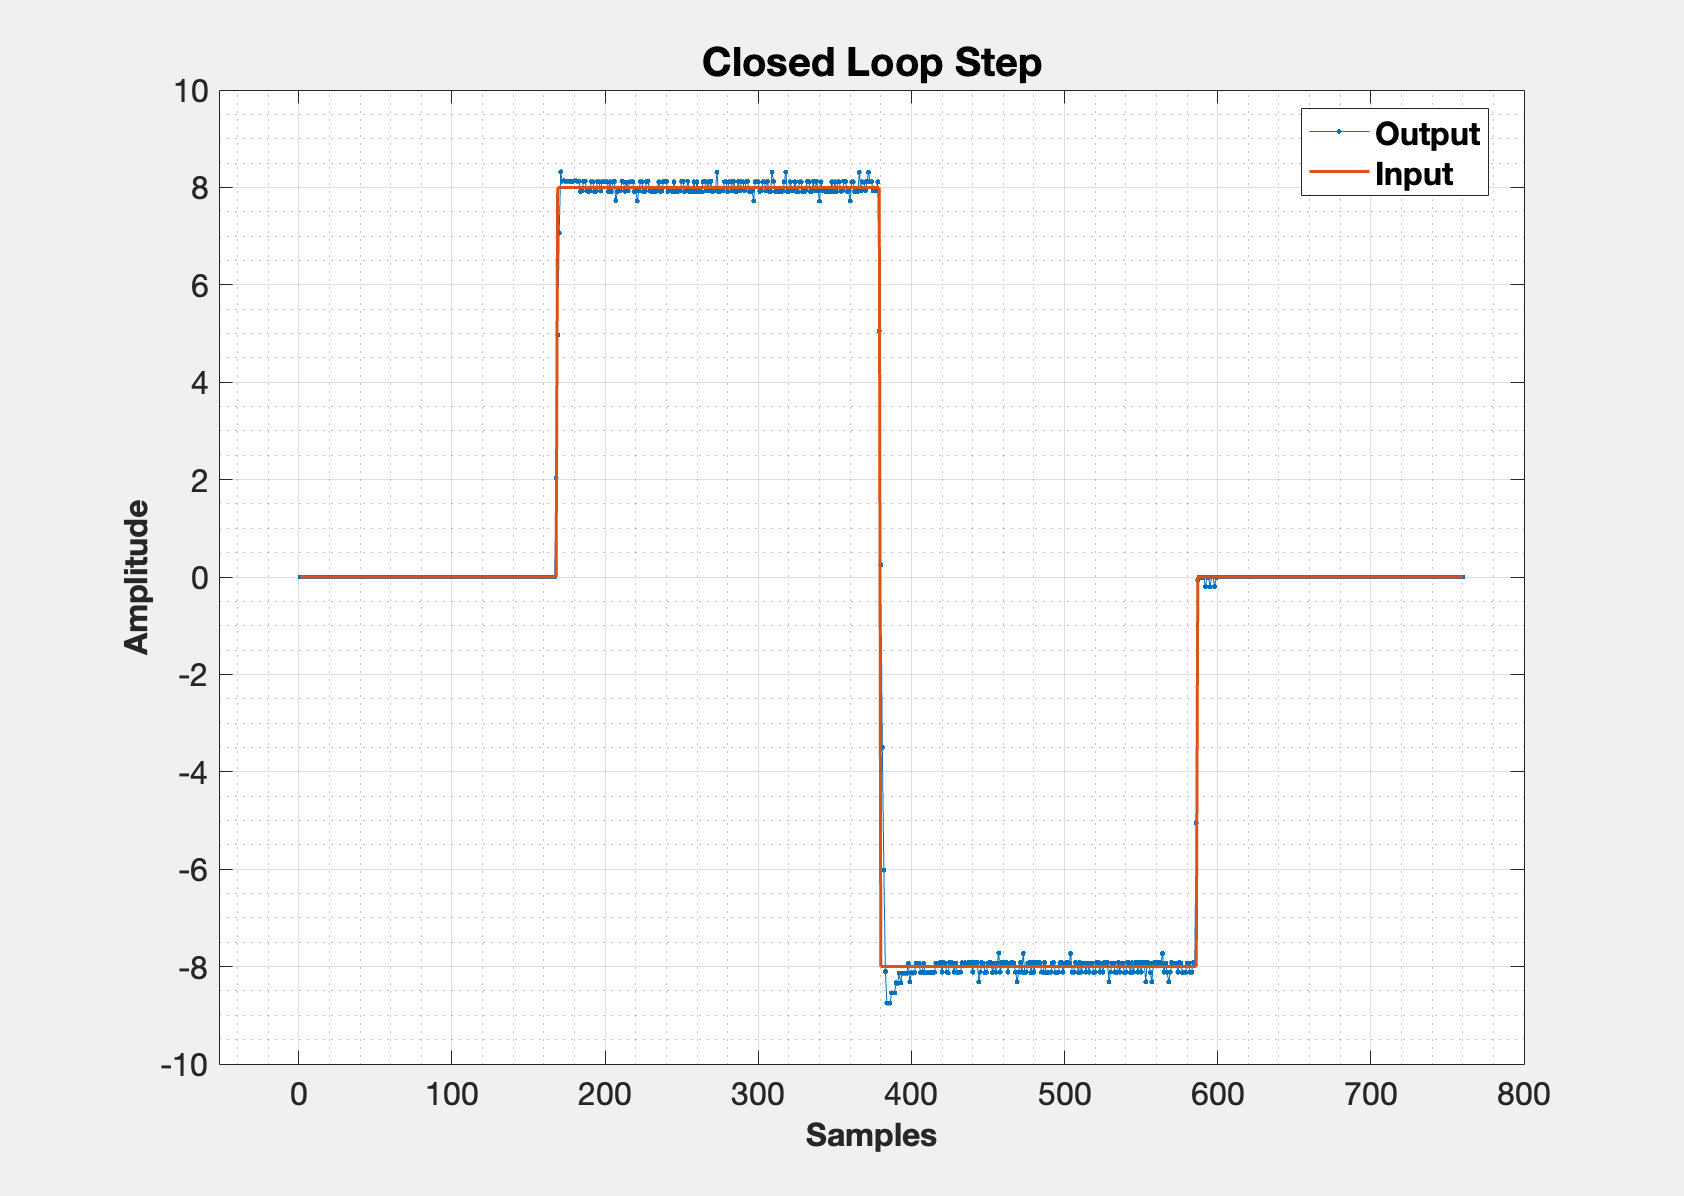

graphInOutData(cl_step_rps, cl_step_ref, 'Closed_Loop_Step', folderpath, ['Ref', 'RPS']);

%%%%%%%%%%%%%%%%%%%%% Input-output plotting helper function
function graphInOutData(outputData, inputData, plotTitle, folderpath, legendNames)
    % Check if the legendNames is provided, otherwise default to "Output" and "Input"
    if nargin < 6
        legendNames = {"Output", "Input"};
    end

    % Replace underscores with spaces for the plot title (but not the filename)
    plotTitleFormatted = strrep(plotTitle, '_', ' ');

    fig = figure;
    plot(outputData, 'Marker', '.');
    hold on;
    plot(inputData, '-', 'LineWidth', 1.5);
    hold off;

    grid on; grid minor;
    legend(legendNames, 'Location', 'best', 'FontWeight', 'bold');
    xlabel('Samples','FontWeight', 'bold');
    ylabel('Amplitude', 'FontWeight', 'bold');
    axis padded;
    fontsize(16, "points")
    title(plotTitleFormatted, 'FontSize', 20, 'FontWeight', 'bold'); 
    % Export plot to pdf
    filepath = fullfile(folderpath, plotTitle + ".pdf");
    set(fig, 'Units', 'inches', 'Position', [0 0 11.7 8.3]);
    set(gcf,'Visible', 'on');
    exportgraphics(fig, filepath);
end